# 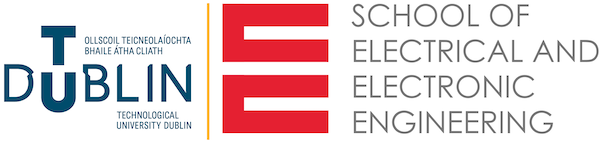

# Fault Analysis Report

Stephen Sheridan C16746195

DIT021A/4

Lecturer Dr. Jane Courtney

December 8th 2019

## Instructions

To run the code simply choose run above. once the livescript is running the settings can be changed in the settings section, the relevent diagrams will be displayed and the results will be automatically calculated. 

There are settings for the fault impedance, the fault type and the faulted bus.

**For the best viewing experience select the 'Show outputs inline' option to the right.**

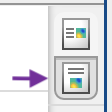

## Introduction

Modelling how a system behaves in a sustained fault scenario is an important excercise for any power network or connected equipment. This report sets out to demonstrate the technique of using symmetrical components to calculate fault currents and voltages for a given network and a number of fault conditions. The method of using symmetrical components shall be explained, demonstrated and discussed.

Two types of fault can be modelled with this script, balanced three phase and Line to Line. These are not the most common faults as balanced faults count for around 5% of faults and line to line count for 5% to 10% [1]. A typical cause for line to line faults would be swans flying into power lines and a symmetrical fault could conceivably be caused by farm or construction machinery crossing the lines.

## Theory

Calculating the voltages and currents of a balanced three phase network  can be performed on a per phase basis using Ohms law, standard circuit theory etc. In the case of an unbalanced fault however it can be considerably more complex. One technique commonly used to solve unbalanced conditions is the use of symmetrical components. The three symmetrical components are negative sequence, positive sequence and zero sequence. Using these three vectors, the vectors of all fault conditions can be constructed. 

 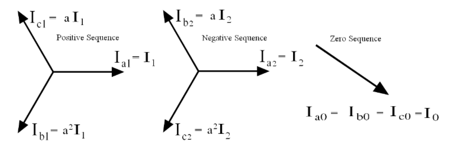[2]

#### *Figure **1** Positive, negative and zero sequence components*

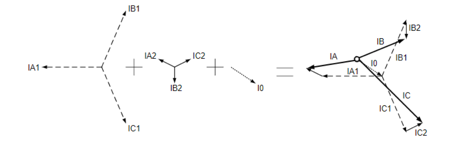[2]

#### *Figure **2** Summing symmetrical components to represent an unbalanced fault*

Taking a three phase network as three separate components we can create a Thévenin equivalent of each that can then be connected to form an equivalent circuit representing the fault being studied. This circuit can then be used to perform analysis applying ohms law etc before converting the results back to phase values.

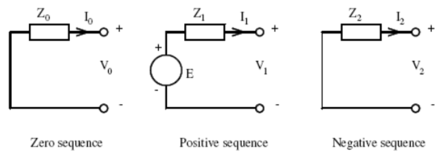 [2]

#### *Figure **3** Thévenin equivalent circuits*

To convert between phase values and their symmetrical components the A matrix is used. The A matrix can be seen below where the a operator represents a shift of 120°, (a = $1\angle 120$°).

It is also useful to know that 1 + a + a2 = 0 and 1 – a = $\sqrt{3}\angle -30°$

 [2]

Conversely

[2]

This code utilises the information above and calculates the fault condition voltages and currents by following these steps.

- The fault type, fault impedance and faulted bus are chosen in the settings.

- All known values are loaded into the workspace

- Thévenin equivalent impedances are calculated according to the chosen faulted bus

- Impedances are converted to per unit values

- Using the Thévenin equivalent circuit, the symmetrical component currents and voltages are calculated

- The symmetrical component values are converted into phase values using the A matrix

- Phase values are finally converted back fro per unit to volts and Amps

## Settings

- **Please input the fault impedance in ohms using the sliders in the form a+bi. For large impedances the multiplier can be used**

re=0;% Set the real component here
im=0;% Set the imaginary component here
mul=1;% Set the multiplier value here
Zfault=(re*mul)+(im*mul*1i)

Zfault = 0

        2.** Please choose a bus to fault**

bus=1 

bus = 1

        3. **Please choose a fault type, choose 0 for 3 phase balanced or 1 for line to line**

fault=0

fault = 0

        4. **To generate a full PDF report including the code please select 1.**

report=0

report = 0

## Input the known values

% Per unit fault voltage
E=1;

% Per unit Impedances
G1= [0.1i 0.1i 0.05i];
T12=[0.1i 0.1i 0.1i];
L23=[0.05i 0.05i 0.1i];

% Calculate the Thévenin equivalent of the impedances and load the
% appropriate image for figure 4
if bus==1
    Vbase = 1e3;
    fig4=imread('bus1.png');
    Zth=(G1.*(T12+L23))./(G1+(T12+L23));
elseif bus==2
    Vbase = 5e3;
    fig4=imread('bus2.png');
    Zth=(L23.*(T12+G1))./(L23+(T12+G1));
elseif bus==3
    Vbase = 5e3;
    fig4=imread('bus3.png');
    Zth= G1 + T12 + L23;
end

% Load the appropriate image for Figure 5
if fault==0
    fig5=imread('Bal.png');
elseif fault==1
    fig5=imread('LL.png');
end

% Calculate the per unit bases and values
Sbase = 100e6;
Ibase = Sbase/(sqrt(3)*Vbase);
Zbase = (Vbase^2)/Sbase;
Zf=(Zfault)/Zbase;

## System information

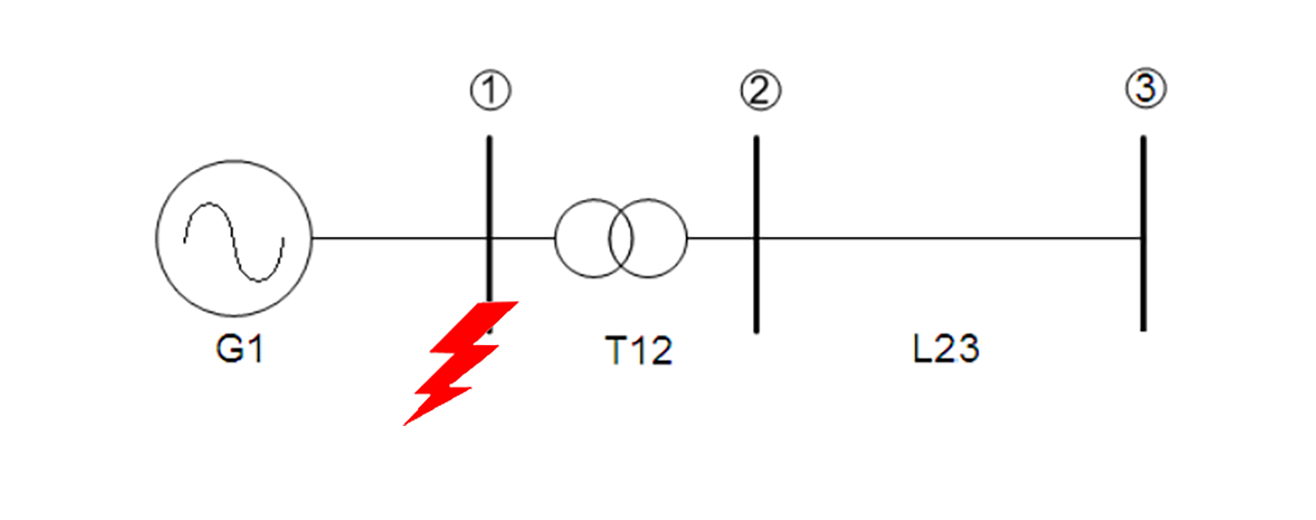

imshow(fig4)

#### Figure.4 System diagram and faulted bus.

Figure 4 shows the network being studied along with the currently chosen fault location.

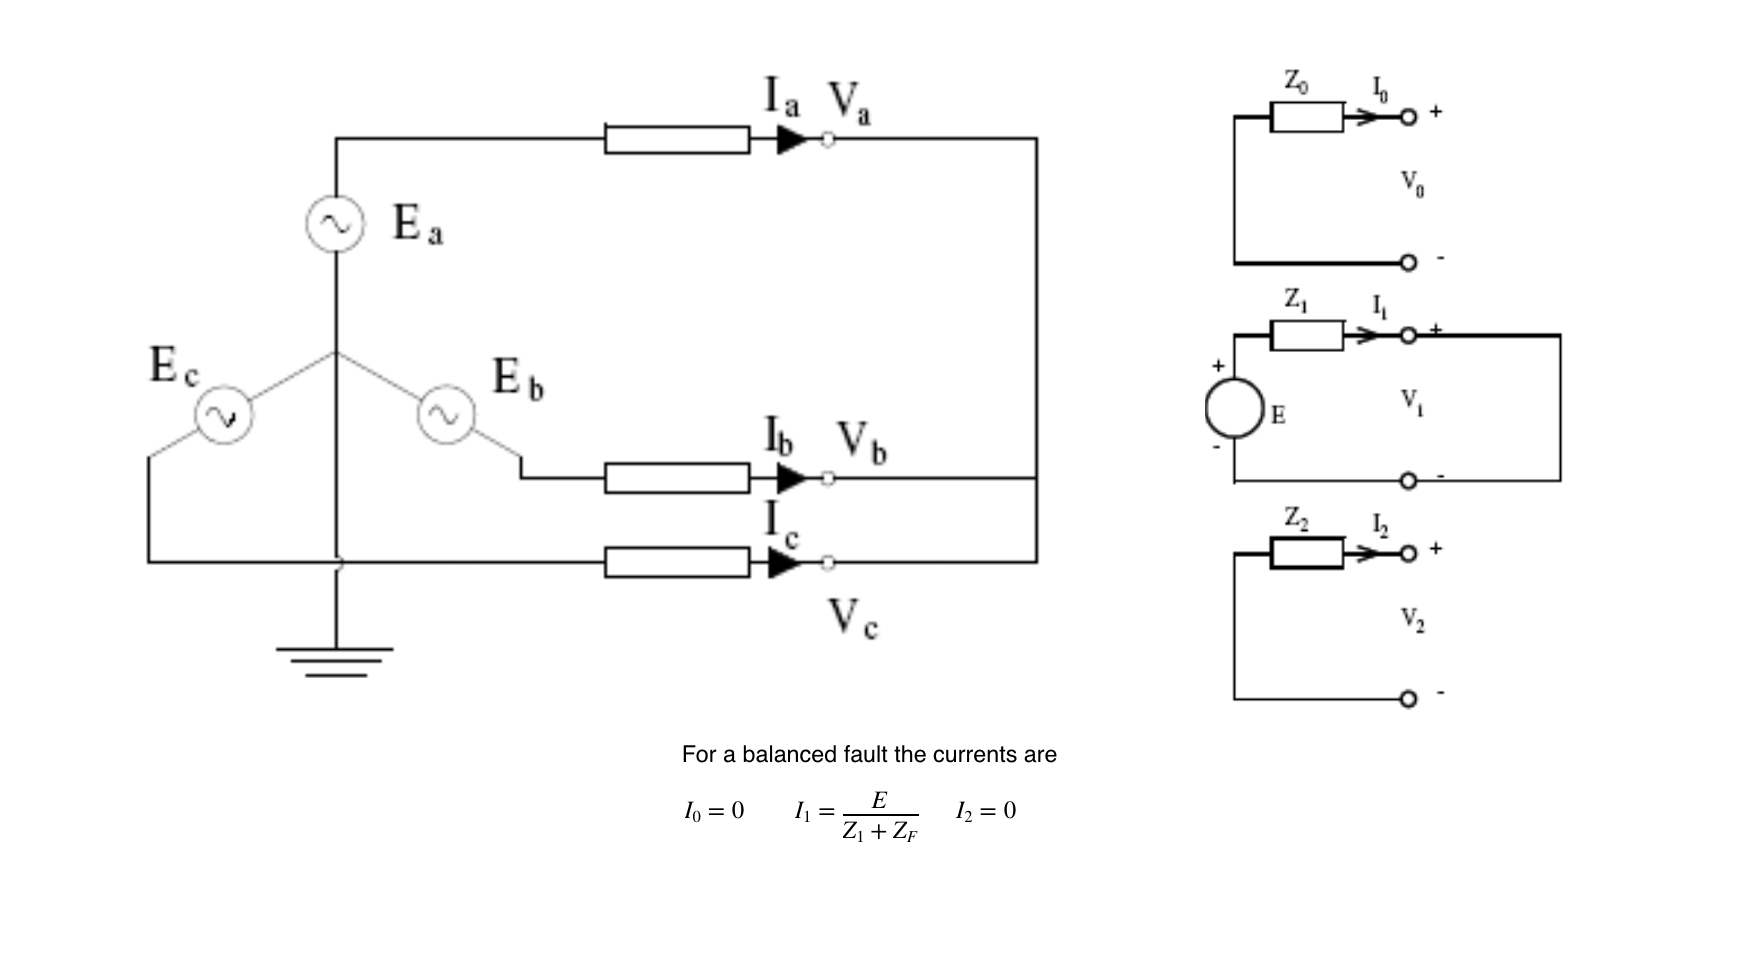

imshow(fig5)

#### Figure.5 Fault circuit diagram and Thévenin equivalent. [3]

Figure 5 shows the circuit diagram, Thévenin equivalent circuits for the sequence components and the equations for the currents for the selected fault type.

## Constructing the A Matrix

% a=1∠120°
x=1; 
y=2*pi/3;
[re,im]=pol2cart(y, x);
a=complex(re, im);

A = [1 1 1; 1 a^2 a; 1 a a^2];

## Calculations

% Sequence circuit calculations
if fault==0
    Vz1=((E*Zth(1))/(Zth(1)+Zf));
    I1 = E/(Zth(1)+Zf);

% Initialise the currents
    I2=0;
    I0=0;
%Calculate V0,v1, v2 for balanced fault
    V0 = -I0*Zth(3);
    V1 = E-(Zth(1)*I1);
    V2 = -I2*Zth(2);

elseif fault==1
% Initialise the currents
    I0=0;
    I1=E/(Zth(1)+Zth(2)+Zf);
    I2=-I1;
%Calculate V0,v1, v2 for unbalanced fault (Line to Line).
    V0 = 0;
    Vzf= I1*Zf;
    V2 = -I2*Zth(2); 
    V1 = E-Vzf-V2;
end

%% Phase calculations

% Calculate the phase currents, Ia, Ib, Ic
IABC=A*[I0 I1 I2]';
% Convert from per unit to Amps
IABC2=IABC*Ibase;

%Calculate phase voltages, Va, Vb, Vc
VABC= A*[V0 V1 V2]';
% Convert from per unit to Volts
VABC2=VABC*Vbase;

## Results

**The sequence impedances in per unit are**

Z0=Zth(3)

Z0 = 0.0000 + 0.0400i

Z1=Zth(1)

Z1 = 0.0000 + 0.0600i

Z2=Zth(2)

Z2 = 0.0000 + 0.0600i

**The sequence impedances in ohms are**

Z0=Z0*Zbase

Z0 = 0.0000e+00 + 4.0000e-04i

Z1=Z1*Zbase

Z1 = 0.0000e+00 + 6.0000e-04i

Z2=Z2*Zbase

Z2 = 0.0000e+00 + 6.0000e-04i

**The sequence currents in per unit are **

I0

I0 = 0

I1

I1 = 0.0000 - 16.6667i

I2

I2 = 0

**The phase currents in per unit are**

IA=IABC(1,1)

IA = 0.0000 + 16.6667i

IB=IABC(2,1)

IB = 14.4338 - 8.3333i

IC=IABC(3,1)

IC = -14.4338 - 8.3333i

**The phase currents in amps are**

IA=IABC2(1,1)

IA = 0.0000e+00 + 9.6225e+05i

IB=IABC2(2,1)

IB = 8.3333e+05 - 4.8113e+05i

IC=IABC2(3,1)

IC = -8.3333e+05 - 4.8113e+05i

**The sequence Voltages in per unit are**

V0

V0 = 0

V1

V1 = 0

V2

V2 = 0

**The phase Voltages in per unit are**

VA=VABC(1,1)

VA = 0

VB=VABC(2,1)

VB = 0

VC=VABC(3,1)

VC = 0

**The phase voltages in volts are**

VA=VABC2(1,1)

VA = 0

VB=VABC2(2,1)

VB = 0

VC=VABC2(3,1)

VC = 0

## Conclusions

It has been shown that the method of symmetrical components can be used to simplify the calculation of fault currents and voltages for both balanced and most importantly unbalanced fault conditions. It has also been shown that a simple Matlab script can be used to perform analysis on a network. It's not too much of a stretch to see that a more complex network could be studied using the methods employed above. 

In practice specialist software packages are used to perform these calculations, however I have first hand experience of one such software package producing incorrect values after an update was rolled out. An engineer in the company was able to verify this by calculating the expected values from first principles demonstrating the merit of having a working knowledge of basic fault analysis. 

## References

[1] T. Agarwal, “Types of Faults and Effects in Electrical Power Systems,” Elprocus, [Online]. Available: https://www.elprocus.com/what-are-the-different-types-of-faults-in-electrical-power-systems/. [Accessed 5 December 2019]  

[2] Dr. Jane. Courtney, “Fault Analysis Notes”

[3] Dr. J. Kearney, “ELECTRICAL POWER SYSTEMS EXPERIMENT 2 SYMMETRICAL COMPONENTS”.

if report==1
    matlab.internal.liveeditor.openAndConvert('Fault.mlx', 'Report.pdf');
end















%       __,_,_,___)          _______
%     (--| | |             (--/    ),_)        ,_)
%        | | |  _ ,_,_        |     |_ ,_ ' , _|_,_,_, _  ,
%      __| | | (/_| | (_|     |     | ||  |/_)_| | | |(_|/_)___,
%     (      |___,   ,__|     \____)  |__,           |__,
% 
%                             |                         _...._
%                          \  _  /                    .::o:::::.
%                           (\o/)                    .:::'''':o:.
%                       ---  / \  ---                :o:_    _:::
%                            >*<                     `:}_>()<_{:'
%                           >0<@<                 @    `'//\\'`    @
%                          >>>@<<*              @ #     //  \\     # @
%                         >@>*<0<<<           __#_#____/'____'\____#_#__
%                        >*>>@<<<@<<         [__________________________]
%                       >@>>0<<<*<<@<         |=_- .-/\ /\ /\ /\--. =_-|
%                      >*>>0<<@<<<@<<<        |-_= | \ \\ \\ \\ \ |-_=-|
%                     >@>>*<<@<>*<<0<*<       |_=-=| / // // // / |_=-_|
%       \*/          >0>>*<<@<>0><<*<@<<      |=_- |`-'`-'`-'`-'  |=_=-|
%   ___\\U//___     >*>>@><0<<*>>@><*<0<<     | =_-| o          o |_==_|
%   |\\ | | \\|    >@>>0<*<<0>>@<<0<<<*<@<    |=_- | !     (    ! |=-_=|
%   | \\| | _(UU)_ >((*))_>0><*<0><@<<<0<*<  _|-,-=| !    ).    ! |-_-=|_
%   |\ \| || / //||.*.*.*.|>>@<<*<<@>><0<<@</=-((=_| ! __(:')__ ! |=_==_-\
%   |\\_|_|&&_// ||*.*.*.*|_\\db//__     (\_/)-=))-|/^\=^=^^=^=/^\| _=-_-_\
%   """"|'.'.'.|~~|.*.*.*|     ____|_   =('.')=//   ,------------.
%       |'.'.'.|   ^^^^^^|____|>>>>>>|  ( ~~~ )/   (((((((())))))))
%       ~~~~~~~~         '""""`------'  `w---w`     `------------'
%     